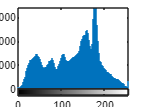

%%%%%%%%%%%%%%%%%%%%
%-----Settings-----%

eyeWidth = 260;   %Distans (px) från sidan till närmsta öga horisontell längd
eyeHeight = 150;  %Distans (px) från topp av bild till närmsta öga

debug = true;
%------------------%4

Files = dir("DB1\db1_01.jpg"); %Läs från mapp

%Skapa bilder på ansiktet
face = imread(Files.folder + "\" + Files.name); % Vanlig
face_eq = histeq(face);                         % Histogramkompenserad
facebw = imbinarize(rgb2gray(face_eq),0.7);       % Trösklad 85%

if debug == true
    imhist(face);
end

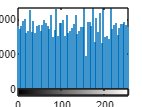


imhist(face_eq)

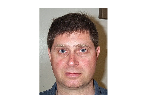


imshow(face);

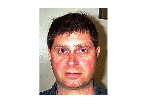

imshow(face_eq);

facebw = uint8(facebw);

meanr = mean(mean(face_eq(:,:,1).*facebw));
meang = mean(mean(face_eq(:,:,2).*facebw));
meanb = mean(mean(face_eq(:,:,3).*facebw));
meanmean = (meanr+meang+meanb)/3;

%Vi vill att alla färgkanaler ska ha samma mean av typ 170
multr = meanmean/meanr;
multg = meanmean/meang;
multb = meanmean/meanb;

face(:,:,1) = face_eq(:,:,1)*multr;
face(:,:,2) = face_eq(:,:,2)*multg;
face(:,:,3) = face_eq(:,:,3)*multb;

face_BW = rgb2gray(face);
face_BW_eq = histeq(face_BW); 

max(max(face_BW))

ans = uint8
247

min(min(face_BW))

ans = uint8
0

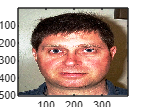


eye1X = eyeWidth;
eye2X = size(face,2) - eyeWidth;
eyeY = eyeHeight;

HSVface = rgb2hsv(face_eq);

% EYE MAP %
YCbCrFace = rgb2ycbcr(face_eq);

image(ycbcr2rgb(YCbCrFace))

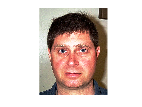


Y = double(YCbCrFace(:,:,1));
Cb = double(YCbCrFace(:,:,2));
Cr = double(YCbCrFace(:,:,3));

% This is weird. should not be purple?
imshow(ycbcr2rgb(YCbCrFace));

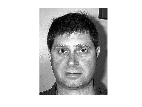

imshowpair(Y, (face_eq)); % Y 

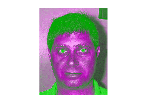

imshowpair(Cb, (face_eq)); % Cb 

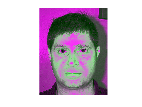

imshowpair(Cr, (face_eq)); % Cr 

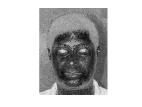

imshow(Cb, [])

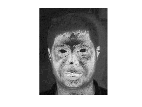

imshow(Cr, [])

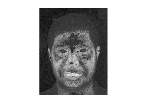


eyeMapC = (Cb.^2 + Cr.^2 + (Cb./Cr))/3;

imshow(eyeMap, []);


eyemapL = 

imshow(eyemapL, [])

Error using images.internal.imageDisplayValidateParams>validateCData
If input is logical (binary), it must be two-dimensional.

Error in images.internal.imageDisplayValidateParams (line 30)
common_args.CData = validateCData(common_args.CData,image_type);

Error in 



size(face)





